# Function ReadMe's

- Section 1: runSolver

- Section 2: assemble

- Section 3: newtonIterate

# Section 1: runSolver

#### File: runSolver.m

## Use:

#### [xNomPlot, MPlot,x,M,t] = runSolver(C, dCxdp, G, dGxdp, F, dFdx, B, lnth, h, t, path)

**xNomPlot: **Returns a figure containing the plot for x(t) nominal.  Every x is on one graph as a funciton of time.

**MPlot: **Retruns a list of figures containing the plot for M(t).  The first plot will be the first column of M(t), which will contain dx/dp for every x over the first parameter.  There will be one plot per column, each plot containing the sensitivity of every X for the same parameter.

**x:** Returns a matrix containing the value of x at every timestep.  There will be one row per number of x parameters, and one column for every time evaluated.  The vector x(:,n) returns the vector x(n) where n is the n'th timestep

**M: **Returns M(t), the intended sensitivity matrix.  This is an array with one row and the number of columns equal to the number of p parameters.  Each cell is a matrix where each colum is the solution at a different timestep.  For example, with 3 x's, 2 parameters, and 100 timesteps, M = {3x100 matrix, 3x100 matrix}, and [M{1}(:,n),M{2}(:,n)] is the M(t) matrix at timestep n.

**t:** this is a row vector containing the time at each timestep.  For example, the plot xNomPlots contains the points (x,t).  t(n) is the actual time corosponding to each timesetp.

* You can say [xPlot,MPlots] = runSolver(parameters) if you only want the plots.  Accepting all outputs is optional.

## Paths

#### **0:** Circuit contains no non-linear or energy storage components

Set path = 0

Variables ignored: C, dCxdp, F, dFxdp

#### **1:** Circuit contains nonlinear components, and does not contain energy storage components

Set path = 1

Variables ignored: F, dFxdp

#### **2:** Circuit contains energy storage components, and does not contain nonlinear components

Set path = 2

Variables ignored: C, dCxdp

#### **3:** Circuit contains both energy storage components and  nonlinear components

Set path = 3

No variables ignored

## Parameters

**C:** Square x by x matrix containing values of capacitors (C in F) and inductors (1/L in 1/H).

**dCxdp:** Array containing p rows with two columns.  The first is a verticle vector stamp, the second is a horozontal vector containing the two nodes [vH,vL] where the order of vH and vL corospond to the stamp.  Matrix size x by p requiring assembly.  This is the jacobian over p of C multiplied by the x vector.

**G: **Square x by x matrix containing values of passive components.  Resistors are in conductance (g = 1/R S)

**dGxdp: **Array containing p rows with two columns.  The first is a verticle vector stamp, the second is a horozontal vector containing the two nodes [vH,vL] where the order of vH and vL corospond to the stamp.  Matrix size x by p requiring assembly.  This is the jacobian over p of G multiplied by the x vector.

**F: **Array containing three columns and one row for each nonlinear circuit component.  The first column is the vertical vector stamp length x, the second column is the devises associated function I=f(x), the third is a horozontal vector containing the two nodes [vH,vL] where the order of vH and vL depend on the chosen current direction.  Column vector of length x requiring asselbly.

**dFdx: **Array containing x rows of three columns.  The first column is an x by x matrix stamp, second is the functions associated function derivitive dI/dx = f(x), the third column is identical to F.  Matrix size x by x requiring assembly.

**B:** Array containing three columns and one row per independant source.  Row 1 containins a column vector length x containing the stamp (1 where current enters and -1 where current leaves), column 2 contains the associated function of time f(t), column 3 contains a single constant.  It is 1 if the function depends on time, and 0 if the function is constant.  Column vector of length x requiring asselbly.

**lnth: **column vector with the length of the vectors x and p [length of x, length of p]

**h: **timestep

**time: **length of time the simulation should calculate

**path: **which runpath the cirucit will take.  Values from 0 to 3.

### Error handling for wrong data types/dimensions needs to be added

### Guessing initial values needs to be added

### Troubleshoot path 3 x nominal- incorrect V2

### The last few values are nonsense (for example the derivitive calculator drops the last 2 due to interpolating twice), figure out how many get dropped, add them to the time, and remove them from the plot to get the full time of good values.  Or find another way to remove bad values.

# Section 2: assemble

#### File: assemble.m

## Use:

#### assembled = assemble(array, xCurrent, t, lnth, type)

Assembles the array format into constant vector or matrix format at the desired x or t.

## Types

#### B: Assembles the B vector

Set type = "B"

Variables ignored: xCurrent

#### C: Assembles the dGxdp or dCxdp matrix

Set type = "C"

Variables ignored: t

#### F: Assembles the F vector

Set type = "F"

Variables ignored: t

#### dF: Assembles the dFdx vector

Set type = "dF"

Variables ignored: t

## Parameters

**array:** these are the F, dFdx, dCxdp, dGxdp, and B arrays described in the ***Section 1: runSolver*** parameters.

**xCurrent:** this is the x parameter to be subbed into the function.  It should be a column of the vector x inside runSolver.

**t:** the t parameter to be subbed into B(t).  It should be a value from the t vector inside runSolver.

**lnth: **this is exactly the lnth parameter in ***Section 1: runSolver***.  Used to size matricies.

**type:** this is the type of array passed to the function.  Ensure correct assembly.

### Error handling for wrong data types/dimensions needs to be added

# Section 3: newtonIterate

#### File: newtonIterate.m

## Use:

#### xConverged = newtonIterate(xStart, G, V, F, dFdx, C, h, lnth)

Returns a column vector length x containing the value of x at the timestep at which it is evaluated. 

It is not a general newton function because vectors need to be assembled correctly inside the function.  It is very specific to path 1 and 3.  Pass the runSolve parameters and you will get x nominal at that timestep.

## Paths

This function is used in two places only: solving for x nominal on path 1, and solving x nominal within the difference equasion in path 3.  It is not used at all in solving for M(t).

**In both cases:** f = (G + C/h)x+F(x) - V, and dfdx = G + C/h + dFdx

**On path 1:** C = 0 and V = B(t).  B(t) should be assembled outside the equasion and passed as the constant vector V.

**On path 3:** the C matrix is present, and V = B(t) + (C/h).*x, where t is t(n+1) and x is x(n) in the difference equasion.  These are known and again are evaluated beforehand and passed as the constant vector V.  Solving for x gives x(n+1) in the difference equasion.

## Parameters

**xStart:** starting guess.  Use the previous xConverged value after the first timestep.  

The other parameters are exactly the runSolve parameters.

### It is still undecided how the origional guess will be made

### Nonconvergence is not handled.  For now it terminates the program with an error message.

clc
clear

# Section 4: numaricalDerivitive

#### File: newtonIterate.m

## Use:

#### function dxdt = numaricalDerivitive(x,h,numTimeSteps)

Returns a list of x values the same dimensions as the incoming x that contain the numarical values of dx/dt, assuming x was some function x(t). 

 It is assumed that the corosponding t values are spaced apart evenly by h.  The value dxdt will corospond to the same values of t.  

The more timesteps the better the result will be. 

## Test

% Controls
numTimeSteps = 28;
h =0.5;

% Setup
x = zeros(1,numTimeSteps);
for i = 1:numTimeSteps
    x(i)= (i-1)*h;
end
y = (x-5).^3+8;
dy = 3*(x-5).^2;
dydx = numaricalDerivitive(y,h,numTimeSteps);

 -117.0000  -83.1250  -56.0000  -34.8750  -19.0000   -7.6250         0    4.6250    7.0000    7.8750    8.0000    8.1250    9.0000   11.3750   16.0000   23.6250   35.0000   50.8750   72.0000   99.1250  133.0000  174.3750  224.0000  282.6250  351.0000  429.8750  520.0000  622.1250



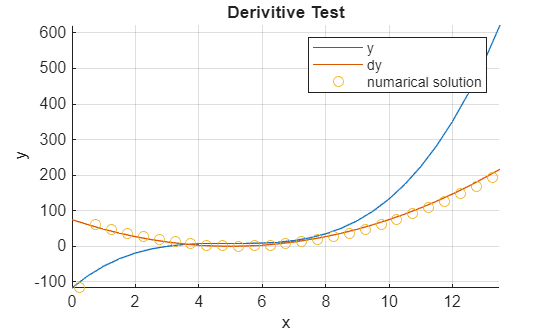


% Plot
figXNom = figure;
hold on
grid on
xlim([x(1), x(end)]);
ylim([min(y), max(y)]);
xlabel("x");
ylabel("y");
title("Derivitive Test");
plot(x,y);
plot(x,dy);
plot(x + h/2,dydx,"o");
legend("y","dy","numarical solution");
hold off

### The last 2 values are nonsense because this function operates by interpolating twice